# **Flower Classification**

## Dataset

#### path to flower photos

% load from saved workspace. to not run again
% load workspace_variables\workspace_var

% here its in same directory as the matlab file, if not provide the path (eg: C:\....)
path = "Data\flower_photos";

#### datastore creation

ds = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

#### Split into randomized training and testing sets

rng default
[trainImgs,testImgs] = splitEachLabel(ds,0.6,"randomized");

## Preprocessing

#### Get Network and its layers

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


#### input layer properties, getting the requirement

ly = net.Layers;
ly1 = ly(1).InputSize;
inputSZ = ly1(1:2);

#### updating datastore size

trainImgs = augmentedImageDatastore(inputSZ, trainImgs);
testImgs = augmentedImageDatastore(inputSZ, testImgs);

#### Number of categories

categos = numel(categories(ds.Labels));

## New Network

### modify GoogLeNet

#### layers

layers = layerGraph(net);

#### Modify the classification and output layers

% fully connected layer
newFc = fullyConnectedLayer(categos,"Name","fc_nw");
layers = replaceLayer(layers,"loss3-classifier",newFc);

% output layer
newOut = classificationLayer("Name","out_nw");
layers = replaceLayer(layers,"output",newOut);

## Training algorithm

#### Training algorithm is set to SGDM

% learning rate set to 0.001
options = trainingOptions("sgdm", ...
    'MaxEpochs',20,...
    'MiniBatchSize', 64, ...
    "InitialLearnRate", 0.01, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor", 0.2, ...
    "LearnRateDropPeriod", 5, ...
    "Momentum", 0.9, ...
    "Shuffle","once", ...
    'Plots','training-progress');

## Perform training

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       14.06% |       3.1381 |          0.0100 |
|       2 |          50 |       00:00:56 |       89.06% |       0.2738 |          0.0100 |
|       3 |         100 |       00:02:01 |       93.75% |       0.1722 |          0.0100 |
|       5 |         150 |       00:03:04 |       98.44% |       0.0885 |          0.0100 |
|       6 |         200 |       00:04:08 |      100.00% |       0.0145 |          0.0020 |
|       8 |         250 |       00:05:05 |      100.00% |       0.0065 |          0.0020 |
|       9 |         300 |  

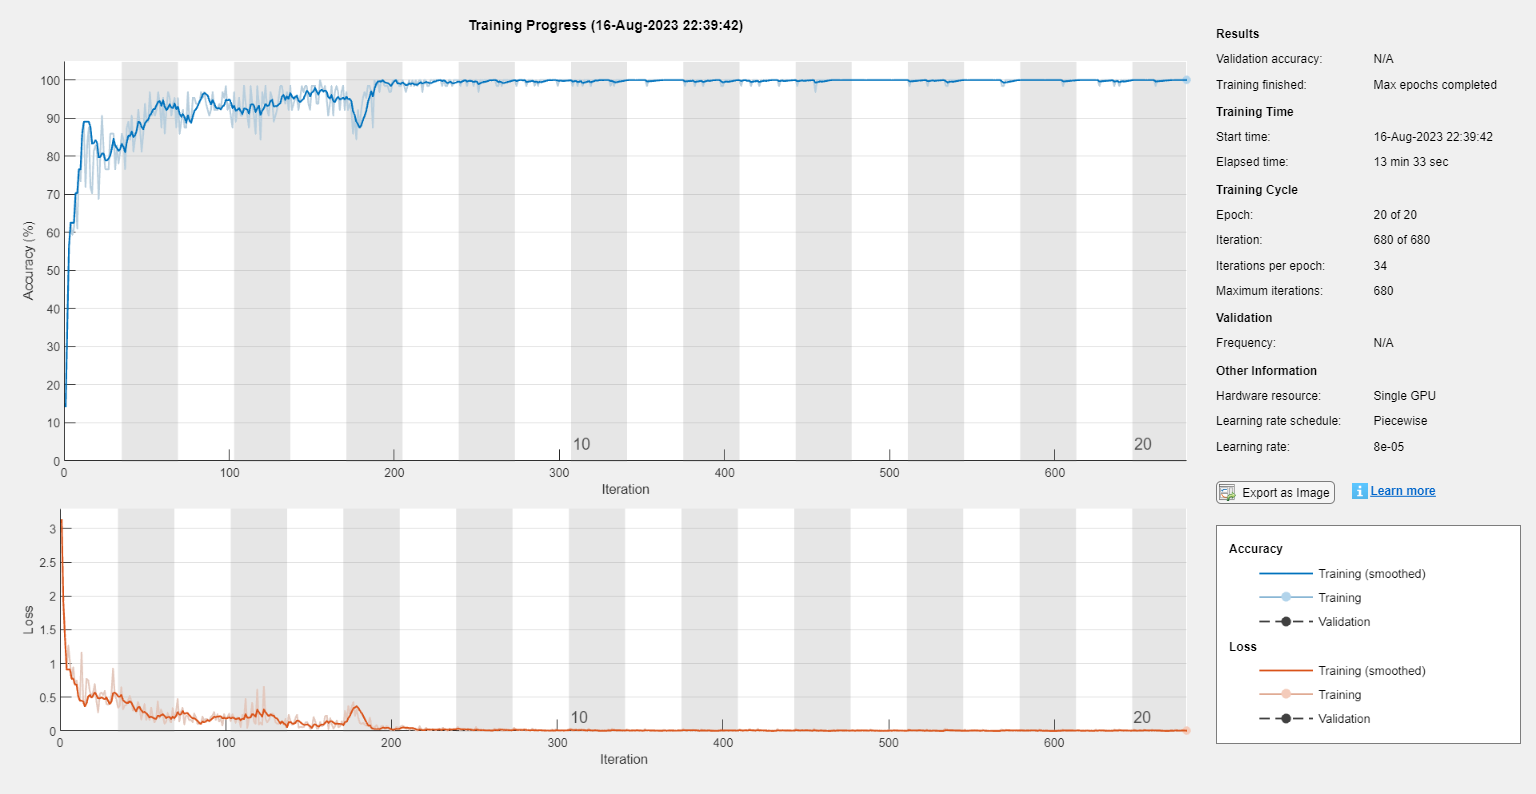

[flowernet,info] = trainNetwork(trainImgs, layers, options);

## Save the new Network

save workspace_variables\flowernet.mat flowernet;

## Test the model

preds = classify(flowernet, testImgs);

## Evaluate the results

#### Accuracy

categ = extractBetween(testImgs.Files, "flower_photos\", "\");
accuracy = nnz(preds == categ) / numel(preds)

accuracy = 0.9212

#### Confusion Matrix

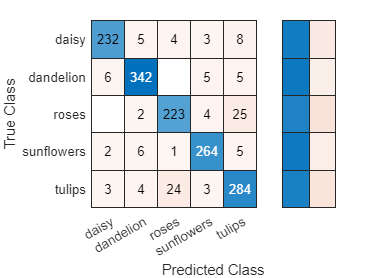

confusionchart(categorical(categ), preds, "RowSummary","row-normalized");

## Analyze misclassifications

#### Confusion matrix

% file of all the test images test set
paths = string(testImgs.Files);

% actual category of the flowers in test set
trueCat = extractBetween(paths, "flower_photos\", "\");

% original
org = categorical(trueCat);

% confusion matrix
cm = confusionmat(org, preds);

% Split into correct and incorrect classifications
% yes is diagonal elements i.e. predicted correctly
yes = diag(cm);

% elements other than diagonal, i.e. wrongly predicted
no = cm - diag(yes);

#### Misclassification rate for each letter

misratebyflwrs = sum(no,2) ./ sum(cm,2);

#### Table with letter names and misclassification rate

flwrs = categories(ds.Labels);

misratebyflwrs = table(flwrs,misratebyflwrs,'VariableNames',["Flowers","MisClassRate"]);

% Sort by worst misclassification
misratebyflwrs = sortrows(misratebyflwrs,"MisClassRate","descend")

misratebyflwrs = 5×2 table
       Flowers        MisClassRate
    ______________    ____________

    {'roses'     }       0.12205  
    {'tulips'    }       0.10692  
    {'daisy'     }      0.079365  
    {'sunflowers'}       0.05036  
    {'dandelion' }      0.044693  


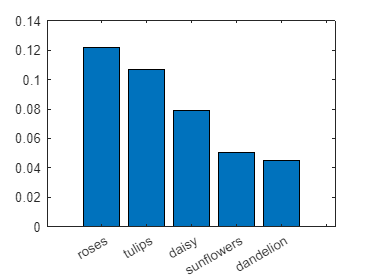

bar(misratebyflwrs.MisClassRate)
xticks(1:26)
xticklabels(misratebyflwrs.Flowers)

## Individual Category misclassification

flw = "roses";

#### True class that were misclassified as something else

% the flower category selected (in drop down menu),
% and select the misclassified among that category
% i.e. category 'flwr' and wrong predcited
misclassidx = (trueCat == flw) & (string(preds) ~= trueCat);

#### Table of the misclassified observations, with the predicted letter

% name of the wrong category predicted, instead of category 'flw'
wrongPred = string(preds(misclassidx));

% files of wrong predicted flowers of category 'flw'
files_categoryPred = paths(misclassidx);

### Plot

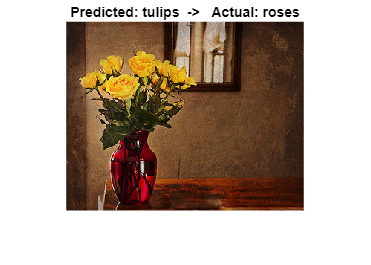

num = numel(wrongPred);

k = 1;

wr_pred_img = files_categoryPred(k);

imshow(wr_pred_img);
title("Predicted: "+wrongPred(k)+"  ->   Actual: "+flw)

#### Saving all the workspace variables to .mat file

save workspace_variables\workspace_var;